clc;clear;

global n_sample; n_sample = 100;
main_dir = 'D:\Data\SimulationData\settingSSoT\n500-k10-p_in2btw4-p_out1btw1';
out_dir = ['D:\Data\Betzel\', main_dir(24:35)];
n_rep = 100;
width = 20;
S = 8;
Ts = ['2';'4';'8'];
rts = ['0'; '2'; '5'];
rss = ['0'; '2'; '5'];

set_dirs = dir(main_dir);
aris_mean = zeros([n_rep,3,3,3]); % T, rt, rs
aris_med = zeros([n_rep,3,3,3]);
aris_max = zeros([n_rep,3,3,3]);
for i_set = 3:length(set_dirs)
    disp(i_set);
    set_dir = set_dirs(i_set).name;
    rep_dirs = dir([main_dir, '\',  set_dir]);
    [T, rt, rs] = get_setting(set_dir);
    [i_T, i_rt, i_rs] = char2index(T, rt, rs);

    for i_rep = 1:length(rep_dirs)-2
        rep_dir = [main_dir, '\', set_dir, '\', rep_dirs(i_rep+2).name];  
%         disp(i_rep);
        [aris_mean(i_rep, i_T, i_rt, i_rs), ...
            aris_med(i_rep, i_T, i_rt, i_rs), ...
            aris_max(i_rep, i_T, i_rt, i_rs)] = summary_rep(rep_dir, width);
    end
end

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29



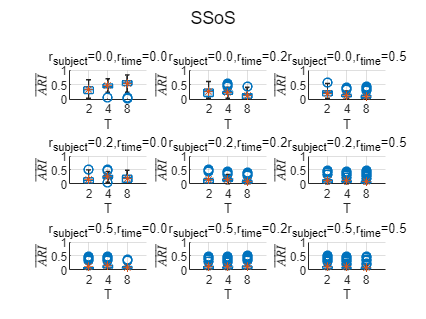

rs_name = ["r_{subject}=0.0", "r_{subject}=0.2", "r_{subject}=0.5"];
rt_name = ["r_{time}=0.0", "r_{time}=0.2", "r_{time}=0.5"];

figure
sgtitle(main_dir(31:34))
for i_rs = 1:3 % index for subject
    for i_rt = 1:3 % index for time
        i_st = 3*(i_rs-1)+i_rt;
        subplot(3,3,i_st);
        ari = aris_mean(:,:,i_rt, i_rs);

        boxchart(ari); 
        grid on
        hold on
        plot(mean(ari,1),'*');

        title(rs_name(i_rs)+","+rt_name(i_rt));
        xlabel("T");
        ylabel('$\overline{ARI}$','interpreter','latex');
        ylim([0,1]);
        xticklabels([2,4,8]);
    end
end

% Store aris matrix for 100 rep, 27 settings as Ali asked
for i_rs = 1:1:3
    for i_rt = 1:1:3
        rs = rss(i_rs);
        rt = rts(i_rt);
        file_name = join([out_dir, '\r_subject=0', rs, '-r_time=0', rt, ".csv"], '');
        data_st = ["T", "S", "replicate_ID", "mean", "median"];
        for i_T = 1:1:3
            T = str2num(Ts(i_T));
            data_T = [repelem(T, n_rep, 1), repelem(S, n_rep, 1), (1:n_rep)',...
                aris_mean(:,i_T, i_rt, i_rs), aris_med(:,i_T, i_rt, i_rs)];
            data_st = [data_st; data_T];
        end
        writematrix(data_st, file_name);
    end
end

function [ari_mean, ari_med, ari_max] = summary_rep(rep_dir, width)
    global n_sample;

    K_edges = 0:width:500;
    ari_i = load([rep_dir,'/aris_ori.mat']).aris;
    z = load([rep_dir,'/z_ori.mat']).zS;
    size_z = size(z);
    K_ori = zeros([size_z(1), size_z(2), size_z(4)]);

    % find the number of communities (K) for each s,t, and sample
    for s = 1:size_z(1)
        for t = 1:size_z(2)
            for sample = 1:size_z(4)
                K_ori(s,t,sample) = max(unique(z(s,t,:,sample)));
            end
        end
    end
    
    % Average among subjects and time
    K_st = mean(K_ori, [1,2]);  % K_st: mean of K among subjects and time
    K_st = reshape(K_st, n_sample, 1);
    [counts,~] = histcounts(K_st, K_edges);
    [~, i_freq] = max(counts);
    K_mask = K_st>= K_edges(i_freq) & K_st<K_edges(i_freq+1);
    
    ari = mean(ari_i,[1,2]);
    ari = reshape(ari, n_sample, 1);
    ari_freq = ari(K_mask);    

    ari_max = max(ari_freq);
    ari_mean = mean(ari_freq); 
    ari_med = median(ari_freq);
end

function [i_T, i_rt, i_rs] = char2index(T, rt, rs)
    switch T 
        case '2'
            i_T = 1;
        case '4'
            i_T = 2;
        case '8'
            i_T = 3;
        otherwise
            i_T = 0;
            disp("wrong T!")
    end

    switch rt
        case '00'
            i_rt = 1;
        case '02'
            i_rt = 2;
        case '05'
            i_rt = 3;
        otherwise
            i_rt = 0;
            disp("wrong rt!")
    end

    switch rs
        case '00'
            i_rs = 1;
        case '02'
            i_rs = 2;
        case '05'
            i_rs = 3;
        otherwise
            i_rs = 0;
            disp("wrong rs!")
    end
end


function [T, rt, rs] = get_setting(set_dir)
    T = set_dir(21);
    rt = ['0', set_dir(7)];
    rs = ['0', set_dir(32)];
end

